PROYECTO 3. S&S SEÑALES Y SISTEMAS. PARTE 1.

Variables Iniciales Generales

n_bits=16;
fs=16000;
n_channels=1;
Td=2;

Punto 1) Grabación y almacenamiento de audios 

Letra O

%Ingrese opcion para grabar los audios:
%AUDIO 1
avisoO1= input('Presione la letra "s" para iniciar la primera grabación: ','s' );
if avisoO1=='s' %Grabar voz
   LetraO1=audiorecorder(fs,n_bits,n_channels,-1); 
   disp('inicia grabacion 1 (2 segundos)');
   recordblocking(LetraO1,Td);
   disp('fin de grabacion 1');
   LetraO_t1=getaudiodata(LetraO1);
   audiowrite('carpeta O/Letra O_1.wav',LetraO_t1, fs);
end

inicia grabacion 1 (2 segundos)


fin de grabacion 1



%AUDIO 2
avisoO2= input('Presione la letra "s" para iniciar la segunda grabación: ','s' );
if avisoO2=='s' %Grabar voz
    LetraO2=audiorecorder(fs,n_bits,n_channels,-1);
    disp('inicia grabacion 2 (2 segundos)');
    recordblocking(LetraO2,Td);
    disp('Fin de grabacion 2');
    LetraO_t2=getaudiodata(LetraO2);
    audiowrite('carpeta O/Letra O_2.wav',LetraO_t2, fs);
end

inicia grabacion 2 (2 segundos)


Fin de grabacion 2



%AUDIO 3
avisoO3= input('Presione la letra "s" para iniciar la tercera grabación: ','s' );
if avisoO3=='s' %Grabar voz
    LetraO3=audiorecorder(fs,n_bits,n_channels,-1);
    disp('inicia grabacion 3 (2 segundos)')
    recordblocking(LetraO3,Td);
    disp('Fin de grabacion 3');
    LetraO_t3=getaudiodata(LetraO3);
    audiowrite('carpeta O/Letra O_3.wav',LetraO_t3, fs);
end

inicia grabacion 3 (2 segundos)


Fin de grabacion 3


Punto 2) Carga, información, visualización de gráficas y reproducción de audios

    %Cargar audios
    audioread('carpeta O/Letra O_1.wav');
    audioread('carpeta O/Letra O_2.wav');
    audioread('carpeta O/Letra O_3.wav');
    
    %Informacion general de las señales de audio
    fs=16000;
    Ts=1/fs;
    N=length(LetraO_t2);
    Td=N*Ts;
    t=[0:Ts:Td-Ts];

    %la misma duracion, frecuencia de muestreo, bits y canales son usados en los 9 audios.
    fprintf('----------------Información General-----------------');

----------------Información General-----------------

    fprintf('La duracion de las señales es de: %6.1f', Td);

La duracion de las señales es de:    2.0

    fprintf('La frecuencia de muestreo de las señales es de: %6.1f', fs);

La frecuencia de muestreo de las señales es de: 16000.0

    fprintf('El número de muestras N de las señales es de: %6.1f', N);

El número de muestras N de las señales es de: 32000.0

    fprintf('El número de bits por muestra de las señales es de: %6.1f', n_bits);

El número de bits por muestra de las señales es de:   16.0

    fprintf('El número de canales de las señales es: %6.1f', n_channels);

El número de canales de las señales es:    1.0


    %Gráficas en tiempo:
    fprintf('-----------Gráficas en tiempo-----------------------');

-----------Gráficas en tiempo-----------------------

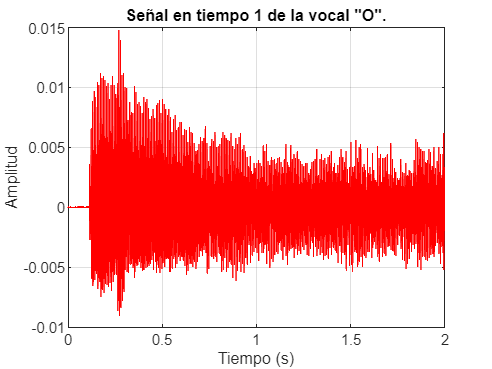

        %O1
    plot(t ,LetraO_t1, 'r-'), grid on
    title(['Señal en tiempo 1 de la vocal "O".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;

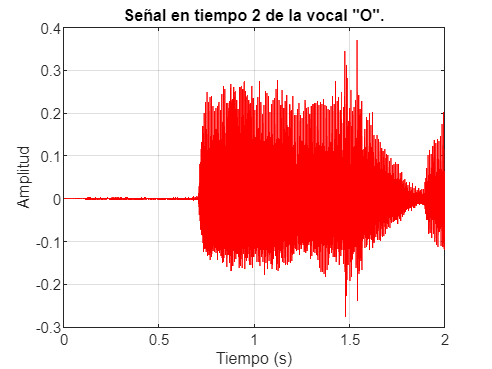

        %O2
    plot(t ,LetraO_t2, 'r-'), grid on
    title(['Señal en tiempo 2 de la vocal "O".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;

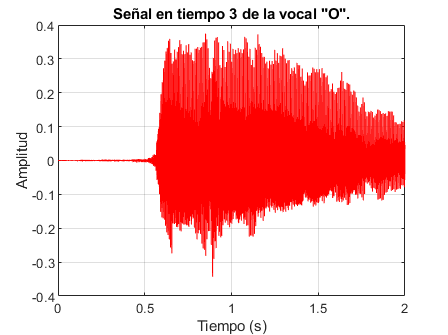

        %O3
    plot(t ,LetraO_t3, 'r-'), grid on
    title(['Señal en tiempo 3 de la vocal "O".']);
    xlabel(['Tiempo (s)']);
    ylabel('Amplitud');
    ax = gca; ax.FontSize = 8;

    
    %Reproducción de audios
    fprintf('-------------Reproducción de audios------------------');

-------------Reproducción de audios------------------

    pause(4);
    disp('Reproduciendo audio O1');

Reproduciendo audio O1


    play(LetraO1);
    pause(4);
    disp('Reproduciendo audio O2');

Reproduciendo audio O2


    play(LetraO2);
    pause(4);
    disp('Reproduciendo audio O3');

Reproduciendo audio O3


    play(LetraO3);

Punto 3) Energía, Transformada de Fourier 

    % Energía total señal 
    fprintf('-----------Energía de las señales--------------------');

-----------Energía de las señales--------------------

    abs_EO1=(abs(LetraO_t1)).^2;
    abs_EO2=(abs(LetraO_t2)).^2;
    abs_EO3=(abs(LetraO_t3)).^2;

    Energy_O1=sum(abs_EO1,"all");
    Energy_O2=sum(abs_EO2,"all");
    Energy_O3=sum(abs_EO3,"all");
    fprintf('La energía en la señal O-1 es: %6.1f', Energy_O1);

La energía en la señal O-1 es:    0.2

    fprintf('La energía en la señal O-2 es: %6.1f', Energy_O2);

La energía en la señal O-2 es:  123.9

    fprintf('La energía en la señal O-3 es: %6.1f', Energy_O3);

La energía en la señal O-3 es:  216.9


    %FFT-Gráficas
    deltaf=1/Td;
    f=[0:deltaf:fs-deltaf];
    fprintf('-----------Gráficas en frecuencia-------------------');

-----------Gráficas en frecuencia-------------------

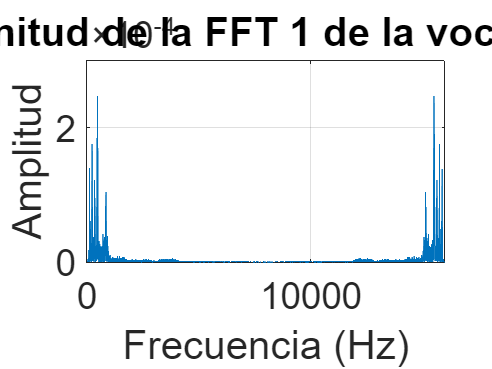

        %O1
    LetraO_f1=fft(LetraO_t1)/N;
    %Frec_O1db = 20*log(abs(LetraO_f1));
    plot(f, abs(LetraO_f1)), grid on
    title(['Magnitud de la FFT 1 de la vocal "O".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;

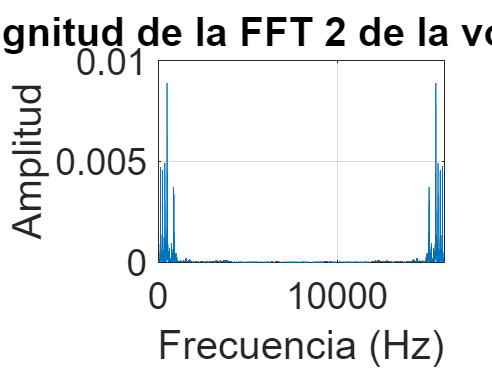


        %O2
    LetraO_f2=fft(LetraO_t2)/N;
    %Frec_O2db = 20*log(abs(LetraO_f2));
    plot (f, abs(LetraO_f2)), grid on
    title(['Magnitud de la FFT 2 de la vocal "O".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;

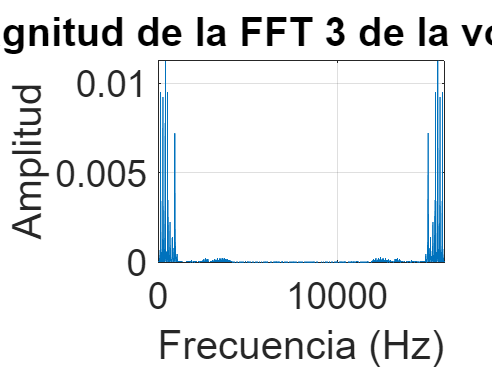


       %O3
    LetraO_f3=fft(LetraO_t3)/N;
    %Frec_O3db = 20*log(abs(LetraO_f3));
    plot (f, abs(LetraO_f3)), grid on
    title(['Magnitud de la FFT 3 de la vocal "O".'])
    xlabel(['Frecuencia (Hz)'])
    ylabel('Amplitud')
    ax = gca; ax.FontSize = 20;


    % Porcentaje de energía de 200Hz - 1200Hz
    fprintf('--------Energía entre 200-1200 Hz-----------------');

--------Energía entre 200-1200 Hz-----------------

        %O1
    rangoO1=LetraO_f1(400:2400);
    MagO1=(abs(rangoO1)).^2;
    SumO1=sum(MagO1,"all")*N;
    fprintf(['La energía (J) en la señal O-1 de 200 Hz a 1200 Hz es: %6.1f'], SumO1);

La energía (J) en la señal O-1 de 200 Hz a 1200 Hz es:    0.1

    Porc_EO1=(SumO1/Energy_O1)*100;
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EO1); 

Su porcentaje de energía es:   45.4

        %O2
    rangoO2=LetraO_f2(400:2400);
    MagO2=(abs(rangoO2)).^2;
    SumO2=sum(MagO2,"all")*N;
    fprintf(['\nLa energía (J) en la señal O-2 de 200 Hz a 1200 Hz es: %6.1f'], SumO2);


La energía (J) en la señal O-2 de 200 Hz a 1200 Hz es:   57.1

    Porc_EO2=(SumO2/Energy_O2)*100;
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EO2);   

Su porcentaje de energía es:   46.1

        %O3
    rangoO3=LetraO_f3(400:2400);
    MagO3=(abs(rangoO3)).^2;
    SumO3=sum(MagO3,"all")*N;
    fprintf(['\nLa energía (J) en la señal O-3 de 200 Hz a 1200 Hz es: %6.1f'], SumO3);


La energía (J) en la señal O-3 de 200 Hz a 1200 Hz es:   95.3

    Porc_EO3=(SumO3/Energy_O3)*100;
    fprintf('Su porcentaje de energía es: %6.1f', Porc_EO3);   

Su porcentaje de energía es:   43.9